# MAT188: Homework 5

## Background

Below is an illustration of the south western portion of the great province of British Columbia. Cities are labelled in blue, and red circles indicate the location of public weather stations. Included with this assignment is temperature data from each of these weather stations. Our goal is to use linear algebra, with the help of MATLAB, to filter noise from the data, detect which weather stations were influenced by ocean temperatures and which were influenced by forest fires.

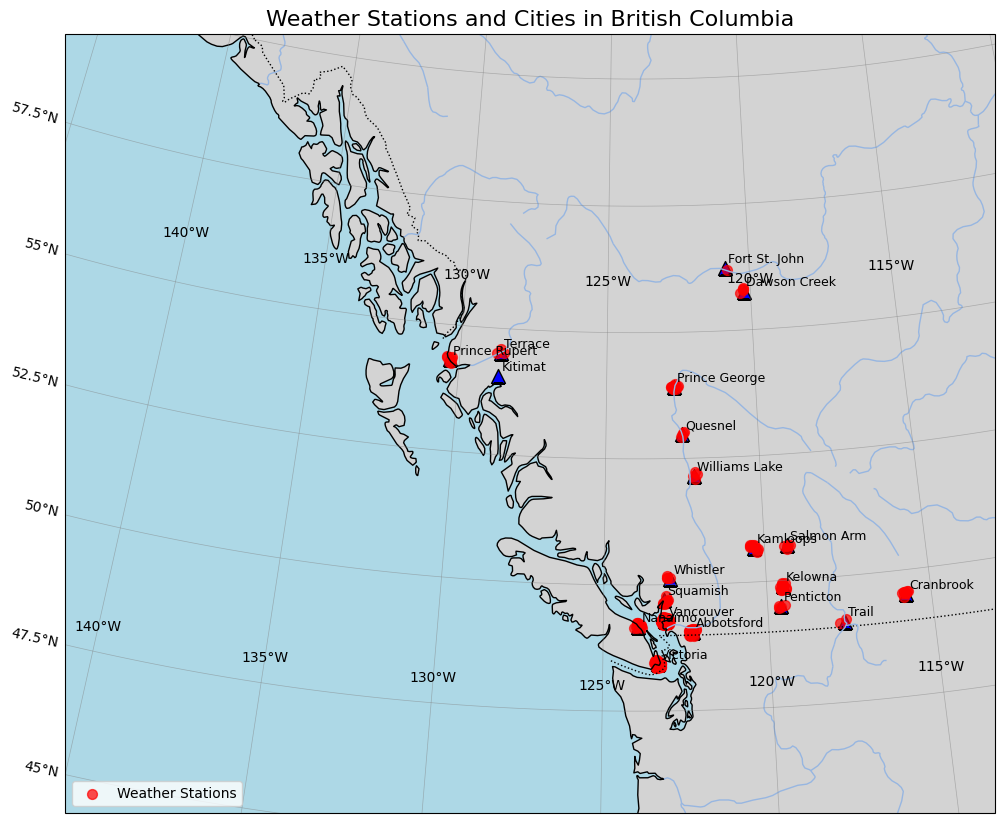

## Part 1

### Step 1: Import weather station data

Begin by loading the temperature data into Matlab script:

- Temperature data from all weather stations, recorded daily in Celcius, are available at https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/temperature.csv

- The locations of each weather station (latitude and longitude coordinates) are available at https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/stations.csv

- Use the `readtable` command to import both CSV files

Hint: `readtable` is able to import data directly from the internet, without needing to download it first.

% Import the data below
data_temp = readtable('https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/temperature.csv');
location = readtable('https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/stations.csv');

### Step 2: Preview and understand the dataset

To get an idea of what the data in the table looks like, use the `summary` function to quickly summarize the dataset.

You can also open the table in the MATLAB GUI by double-clicking on the variable name in your "Workspace".

% Generate summaries of both tables here
summary(data_temp);


data_temp: 1095x201 table

Variables:

    Var1: datetime
    Station_0: double
    Station_1: double
    Station_2: double
    Station_3: double
    Station_4: double
    Station_5: double
    Station_6: double
    Station_7: double
    Station_8: double
    Station_9: double
    Station_10: double
    Station_11: double
    Station_12: double
    Station_13: double
    Station_14: double
    Station_15: double
    Station_16: double
    Station_17: double
    Station_18: double
    Station_19: double
    Station_20: double
    Station_21: double
    Station_22: double
    Station_23: double
    Station_24: double
    Station_25: double
    Station_26: double
    Station_27: double
    Station_28: double
    Station_29: double
    Station_30: double
    Station_31: double
    Station_32: double
    Station_33: double
    Station_34: double
    Station_35: double
    Station_36: double
    Station_37: double
    Station_38: double
    Station_39: double
    Station_40: double
    Stat

summary(location);


location: 200x4 table

Variables:

    Var1: double
    City: cell array of character vectors
    Latitude: double
    Longitude: double

Statistics for applicable variables:

                 NumMissing         Min            Median             Max             Mean             Std    

    Var1             0                   0          99.5000              199          99.5000        57.8792  
    City             0                                                                                        
    Latitude         0             48.4284          49.2827          56.2460          50.1148         1.9365  
    Longitude        0           -130.3208        -123.1207        -115.7694        -122.4558         2.5439  



To get a sense of the imported data, we can also preview the first or last few rows of the table using the `head` or `tail` commands.

Show the first 5 rows of both the temperature and station Data Tables.

head(data_temp, 5);

       Var1       Station_0    Station_1    Station_2    Station_3    Station_4    Station_5    Station_6    Station_7    Station_8    Station_9    Station_10    Station_11    Station_12    Station_13    Station_14    Station_15    Station_16    Station_17    Station_18    Station_19    Station_20    Station_21    Station_22    Station_23    Station_24    Station_25    Station_26    Station_27    Station_28    Station_29    Station_30    Statio

head(location, 5);

    Var1          City          Latitude    Longitude
    ____    ________________    ________    _________

     0      {'Kelowna'     }     49.888       -119.5 
     1      {'Dawson Creek'}      55.76      -120.23 
     2      {'Abbotsford'  }      49.05       -122.3 
     3      {'Nanaimo'     }     49.166      -123.94 
     4      {'Vancouver'   }     49.283      -123.12 



**Let's consider if the imported data makes sense:**

1. Are the values consistent with the dataset description? (eg. daily values in Celcius)

2. What is the date range of the data?

3. How many weather stations do we have data for?

4. In the temperature table, what do rows represent? What do columns represent?

### Step 3: Extract temperature data into matrices

We can index into MATLAB tables using the bracket notation.

Let's first extract the date values:

dates = data_temp.Var1;
locs = location.City;


Next, let's extract all the temperature values from all stations into one matrix:

- From the code examples above, how can we subset a table from all rows of multiple columns by index?

- With a subset table, how can we convert this into a matrix?

tempmtx = table2array(data_temp(:, 2:end));
lat = table2array(location(:, 3));
long = table2array(location(:, 4));

#### Quick sense check:

Verify your variable types in the Workspace.

Are they matrices (NxM double) or tables (NxM table)?

%temptmx, lat, and long are all matricies and 
%data_temp, and locs are tables

### Step 4: Initial visualization

For a better sense of what the temperature dataset looks like, let's plot all the temperature values from every weather station.

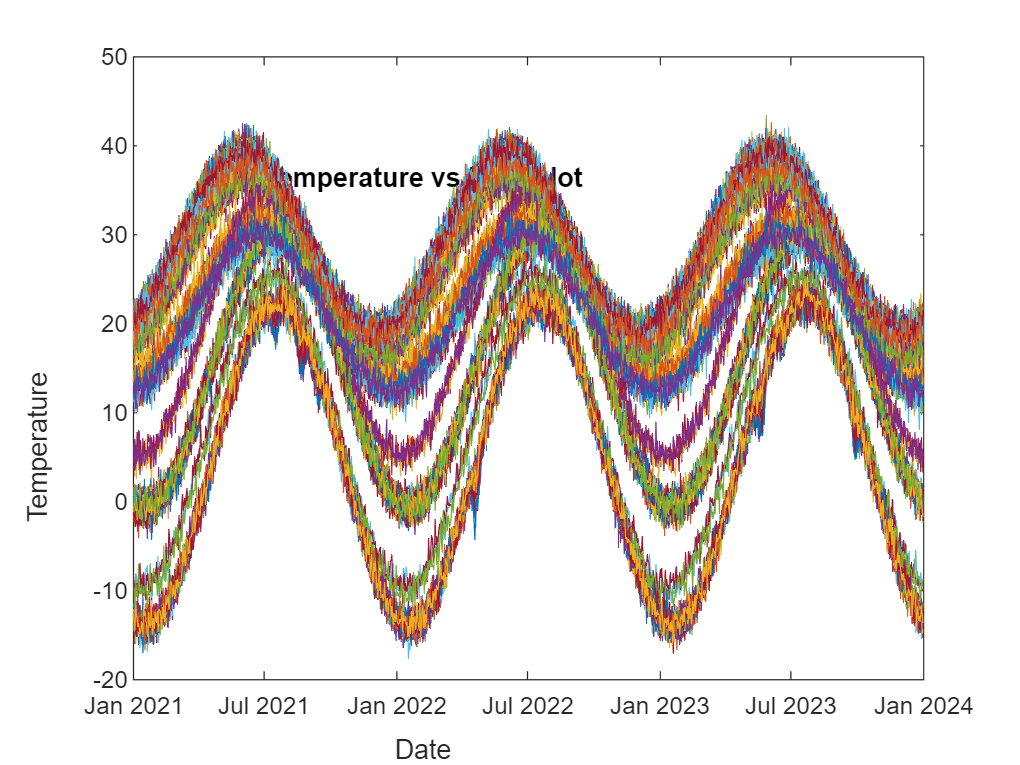

figure;

plot(dates, tempmtx)
xlabel('Date')
ylabel('Temperature')
title('Temperature vs Date plot')

Let's also plot the location (Longitude and Latitude) of all the weather stations as a scatter plot.

- See above for hints on how to customize your plot markers

- Longitude should be on the x-axis, and Latitude should be on the y-axis

- Recall how to access values from a table by variable name! (See Step 3 above)

- Ensure your markers shape, size, and colour are easy to see!

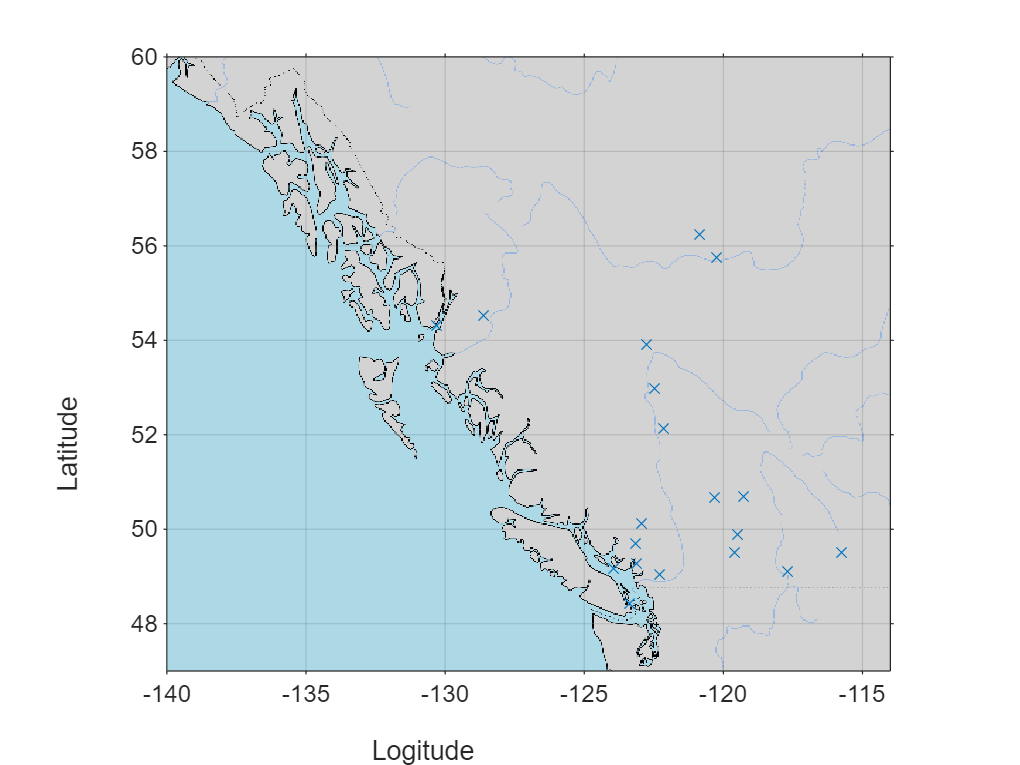

figure;
showmap 
hold on
scatter(long, lat, 'x')
xlabel('Logitude')
ylabel('Latitude')
title('Latitude vs Longitude scatter plot')

### Step 5: Find principal components using eigenvector decomposition

First, we need to mean-center and scale our data:

- For each weather station, **subtract the mean temperature from the temperature timeseries**

- **Divide the timeseries by the standard deviation** of the timeseries

Repeat this for all weather stations.

Hint: What dimension of your matrix corresponds to time? Which dimension do we need to compute the `mean` and `std` along?

[numRows, numStation] = size(tempmtx);
temp_norm = zeros(numRows, numStation);

for station = 1:numStation;
    temp_norm(:,station) = (tempmtx(:, station) - mean(tempmtx(:,station))) / std(tempmtx(:,station));
end

temps_scaled = (tempmtx - mean(tempmtx, 1)) ./ std(tempmtx, [], 1)

temps_scaled =    -1.4057   -1.4958   -1.4920   -1.2485   -1.2324   -1.3056   -1.2511   -1.3738   -1.2413   -1.3891   -1.1341   -1.3100   -1.4216   -1.1600   -1.4367   -1.2627   -1.5438   -1.4366   -1.4717   -1.2702   -1.2115   -1.4840   -1.4582   -1.3008   -1.4342   -1.2628   -1.0256   -1.3770   -1.2958   -1.0788   -1.2506   -1.1703   -1.0517   -1.3856   -1.3741   -1.3830   -1.2155   -1.1736   -1.2507   -1.4275   -1.2138   -1.3642   -1.2446   -1.0797   -1.1155   -1.5145   -1.2497   -1.2257   -1.3214   -1.1549
   -1.4360   -1.3457   -1.1999   -1.3126   -1.1816   -1.2749   -1.2294   -1.3577   -1.0961   -1.2897   -1.1107   -1.4084   -1.3529   -1.3123   -1.0731   -1.2751   -1.0670   -1.2381   -1.3366   -1.3687   -1.1864   -1.4080   -1.0515   -1.5551   -1.3674   -1.3323   -1.1217   -1.2644   -1.3706   -1.3098   -1.0880   -1.1799   -1.0734   -1.2561   -1.3436   -1.3404   -1.3333   -1.4143   -1.3601   -1.4808   -1.2587   -1.2496   -1.3492   -0.8841   -0.8754   -1.3460   -1.6346   -1.3552   -

Find the covariance matrix describing the relationship between the station and the date for the temperature.

C = cov(temp_norm);
display(C);

C =     1.0000    0.9931    0.9165    0.7149    0.6756    0.6875    0.6805    0.9924    0.7301    0.9014    0.6918    0.9917    0.9888    0.7496    0.6912    0.7239    0.7267    0.9912    0.9920    0.6872    0.7060    0.7416    0.7044    0.9920    0.9916    0.9929    0.7217    0.9909    0.7718    0.6889    0.7070    0.7159    0.6989    0.9928    0.9916    0.9920    0.7486    0.7366    0.8646    0.9920    0.7302    0.9923    0.6883    0.6885    0.7121    0.9778    0.7237    0.9914    0.9922    0.6913
    0.9931    1.0000    0.9131    0.7053    0.6660    0.6780    0.6720    0.9924    0.7212    0.8964    0.6819    0.9927    0.9882    0.7417    0.6815    0.7152    0.7181    0.9922    0.9924    0.6773    0.6970    0.7326    0.6952    0.9928    0.9925    0.9939    0.7122    0.9922    0.7631    0.6801    0.6996    0.7069    0.6901    0.9938    0.9926    0.9926    0.7404    0.7279    0.8589    0.9922    0.7211    0.9931    0.6793    0.6788    0.7042    0.9768    0.7146    0.9926    0.9930    0

Find the eigenvalues and eigenvectors of the covariance matrix.

Hint: the 'diag' command may be useful for isolating the eigenvalues.

[V,D] = eig(C)

V =    -0.0282   -0.0045    0.0652    0.0983    0.0312   -0.0009    0.0426    0.1237   -0.1366    0.1169   -0.0310    0.0455    0.0148    0.2504    0.1474    0.0292   -0.1461   -0.0024   -0.0023    0.0220    0.0043    0.0734   -0.0397    0.0075   -0.0252   -0.1082    0.0568    0.0215   -0.1460    0.0454   -0.2030    0.1513   -0.0150   -0.0719    0.1032    0.1683    0.1944    0.0311    0.0722   -0.1287    0.0291   -0.1224   -0.0557   -0.0221    0.1721   -0.0283    0.0154    0.1209    0.1782    0.0374
   -0.1267   -0.0038    0.0974    0.0872   -0.0480   -0.2113   -0.0632   -0.1184    0.0309   -0.1310   -0.0493    0.2408    0.0508   -0.0939    0.0421   -0.2885   -0.0635   -0.0456   -0.2089    0.1570   -0.1206   -0.3566   -0.0158   -0.1587    0.0556   -0.2115   -0.0774   -0.0179    0.1292    0.0239    0.1534    0.0285    0.1382   -0.0283    0.0254   -0.1045   -0.1905    0.0844    0.1195   -0.1666    0.1450    0.0052    0.0699   -0.0150   -0.1124    0.1654   -0.0419    0.0515    0.1156   -0

D =     0.0033         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0034         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

evalues = diag(D);

### Step 6: Let's do some sense-checks

Recall the Eigen decomposition:

        
$$A=V\Lambda \;V^{-1}$$


Which MATLAB variable above corresponds to...

The matrix $V$

The matrix $\Lambda \;$

The matrix $A$

Recall that $V$ is by definition, orthonormal. Let's verify this with MATLAB.

Compute $V^T V$.

v = V'*V

v =     1.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0

Plot this matrix as a heatmap using the MATLAB command `imagesc`.

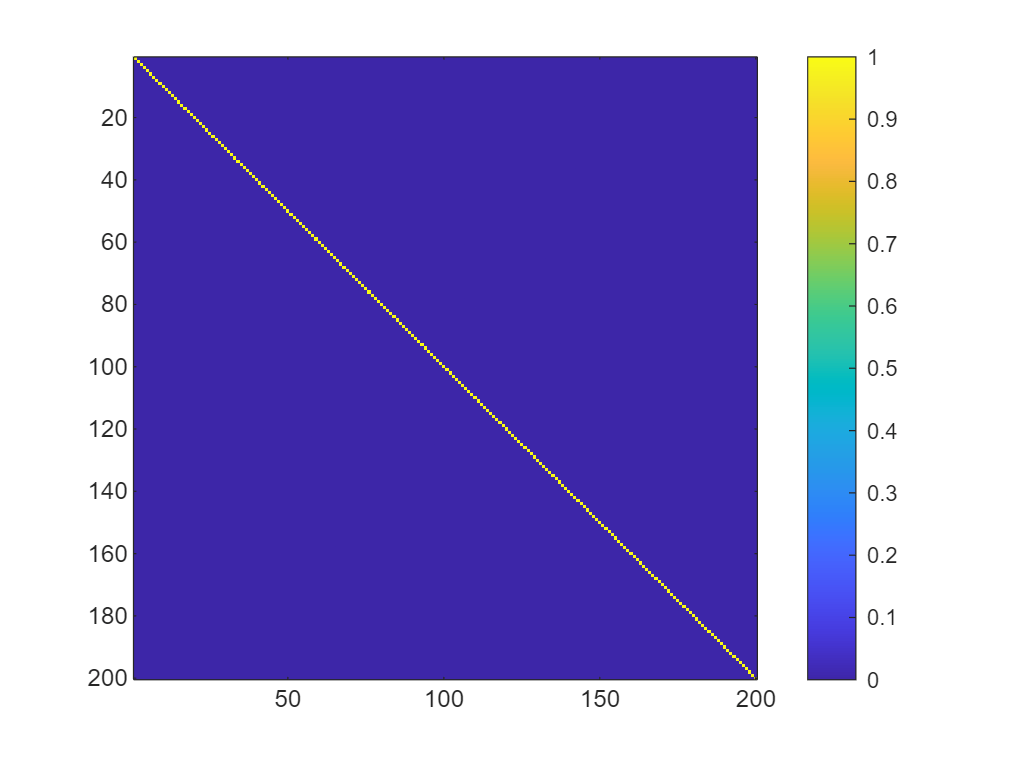

figure; 
imagesc(v)
axis square 
colorbar

Let's also confirm this numerically.

Compute $V^T V-I$, then check that all values in this matrix are zero using the provided `iszero` function.

[vRows, vCols] = size(v);
I = eye(vRows, vCols);
iszero(v - I)

ans = logical
   1


### Step 7: Identifying the directions of maximum variance

Normalize the eigenvalues by dividing each eigenvalue by the total sum.

- These are the eigenvalues from a decomposition of the covariance matrix. 

- The normalized eigenvalues can be interpreted as a fraction of variance in the data captured by each eigenvector (eg. component).

enorm = evalues ./ sum(evalues)

enorm =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


We want to identify the components that encompass the most variance in the data.

Sort the eigenvalues from highest to lowest. Then arrange the eigenvectors correspondingly.

[evaluesorted, sort_index] = sort(enorm, 'descend')

evaluesorted =     0.8677
    0.1165
    0.0003
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


sort_index =    200
   199
   198
   197
   196
   195
   194
   193
   192
   191


Vsorted = V(:, sort_index)

Vsorted =     0.0675    0.0927    0.0574    0.0049   -0.0049    0.0296    0.0042   -0.0132   -0.0337    0.0054    0.0422    0.0144   -0.0101    0.0049    0.0343   -0.0034    0.0464   -0.0036    0.0265    0.0306   -0.0014    0.0119    0.0435   -0.0094    0.0029   -0.0143   -0.0333    0.0092   -0.0405   -0.0132    0.0293    0.0328    0.0106    0.0052    0.0144    0.0536   -0.0416    0.0267   -0.0391    0.0083    0.0231   -0.0018   -0.0055    0.0003    0.0228    0.0154    0.0329   -0.0343   -0.0016   -0.0210
    0.0671    0.0954    0.0672   -0.0008    0.0108   -0.0048   -0.0139   -0.0113   -0.0088   -0.0104    0.0160   -0.0224   -0.0116    0.0262   -0.0024   -0.0290    0.0065   -0.0037    0.0023   -0.0213   -0.0296   -0.0154    0.0040   -0.0008    0.0212   -0.0046    0.0277    0.0392   -0.0012   -0.0338    0.0061    0.0295   -0.0345   -0.0057   -0.0316    0.0058   -0.0213    0.0097    0.0071   -0.0104   -0.0088    0.0103   -0.0017   -0.0071    0.0202    0.0139   -0.0232   -0.0281   -0.021

Plot all the normalized and sorted eigenvalues as a line plot.

- The index of the eigenvalues should be on the x-axis

- The normalized eigenvalue should be on the y-axis

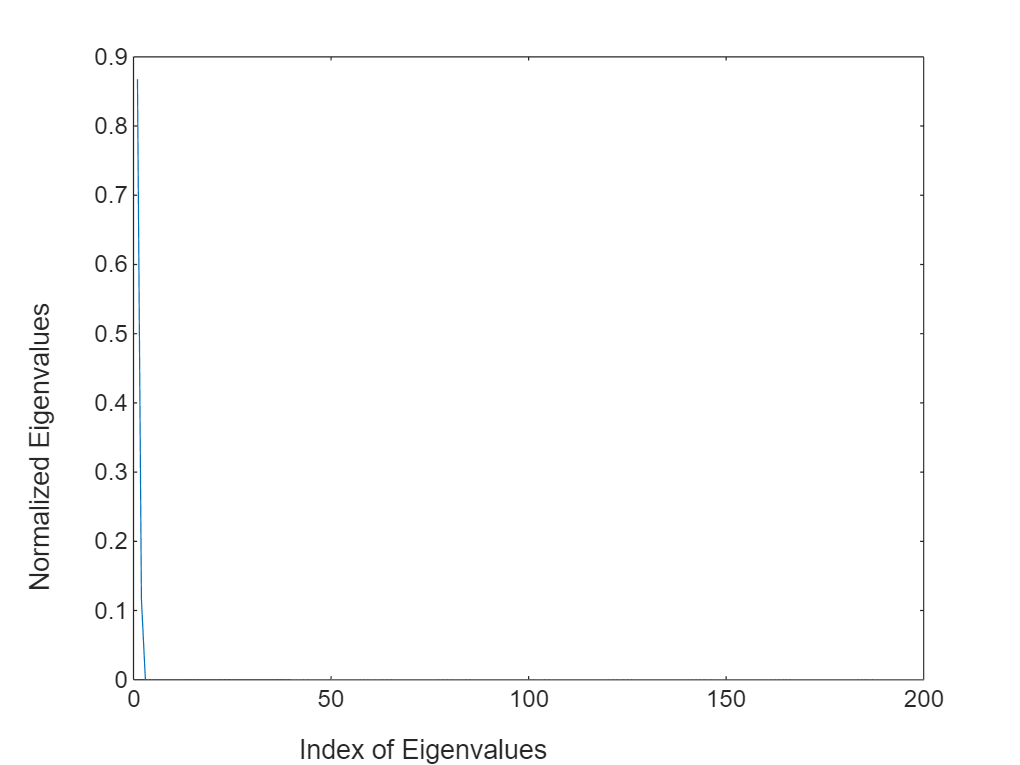

figure 
plot(evaluesorted)
xlabel('Index of Eigenvalues')
ylabel('Normalized Eigenvalues')

Let's zoom into the elbow and take a closer look... (eg. $x\in \left\lbrack 0,10\right\rbrack \;,y\in \left\lbrack 0,0\ldotp 01\right\rbrack$)

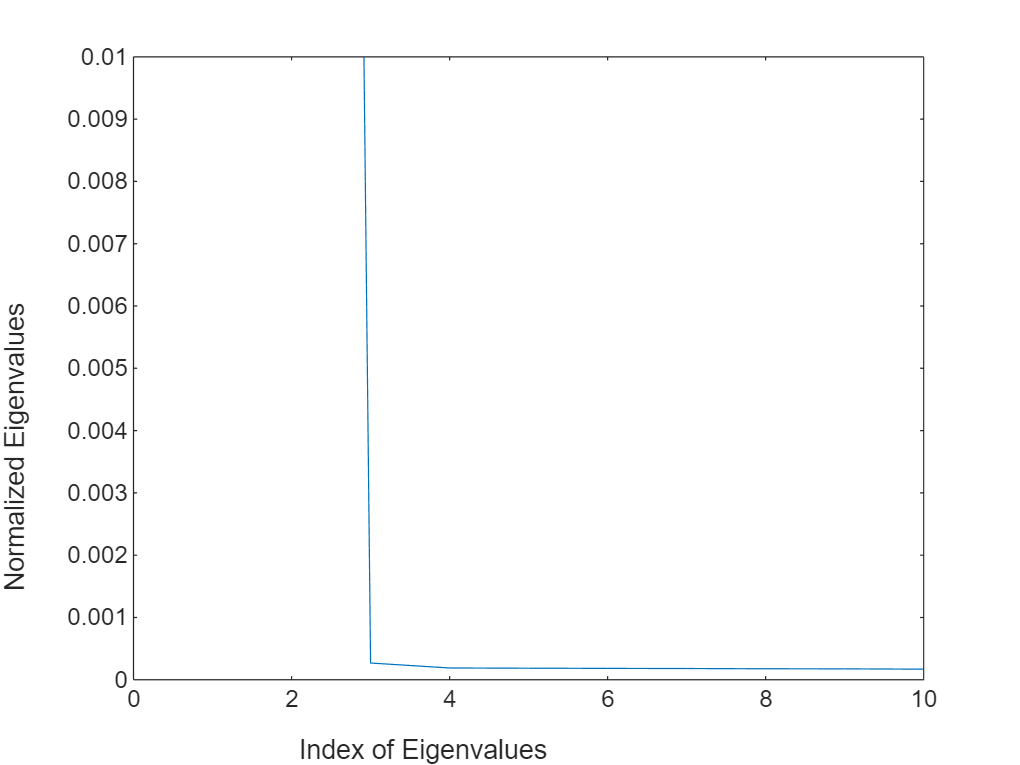

figure 
plot(evaluesorted)
xlim([0 10])
ylim([0 0.01])
xlabel('Index of Eigenvalues')
ylabel('Normalized Eigenvalues')

### Step 8: Project the temperature measurements into the Eigenspace of the covariance matrix

The Eigenspace of the covariance matrix projects the data along directions in which the temperature measurements are maximally linearly correlated.

- Currently, for one day's temperature measurements, each weather station can be considered a dimension/axis

- We will now project every day's temperature measurements into a new space, where the dimensions/axes correspond to a group of weather stations that tend to vary together

For the temperature measurements for each day, project the temperature measurement timeseries into the eigenbases by computing:

    
$$A^{\prime } =\textrm{AV}$$


Aprime = temp_norm * Vsorted

Aprime =   -18.3522   -1.2200   -0.0485    0.1589    0.0050   -0.1416   -0.0479   -0.0110    0.1412   -0.0197   -0.1544    0.0333    0.0447   -0.1362    0.0533   -0.0534    0.2876   -0.2564    0.1745    0.1493   -0.1876    0.1547    0.0229    0.2385   -0.1072   -0.1950   -0.1846    0.0243    0.2351   -0.0738   -0.2936   -0.0441   -0.0234   -0.2728    0.1396   -0.2601    0.0964   -0.0154    0.0237   -0.0158    0.1575    0.2771    0.1586    0.1174   -0.3157    0.1761   -0.0987    0.0426   -0.0636   -0.0804
  -18.3519   -1.2435   -0.0295   -0.0631   -0.3606   -0.1023   -0.2283    0.0574   -0.4029   -0.3008   -0.3940   -0.0591   -0.0662    0.1797   -0.0708   -0.3728   -0.2405    0.2762    0.0466   -0.3544    0.0719    0.0007   -0.1571    0.2404   -0.0213   -0.2020   -0.0082    0.0529   -0.0261    0.2194   -0.4698    0.1332   -0.0013    0.1293   -0.3097   -0.1386   -0.0730    0.1246   -0.1182    0.0874    0.1501   -0.1355    0.0174   -0.0566    0.0911    0.1108   -0.2027    0.3138    0.0249

Now, let's plot the temperature data along the first 5 dimensions over time.

- Be sure to add a title, legend, and label for the x-axis.

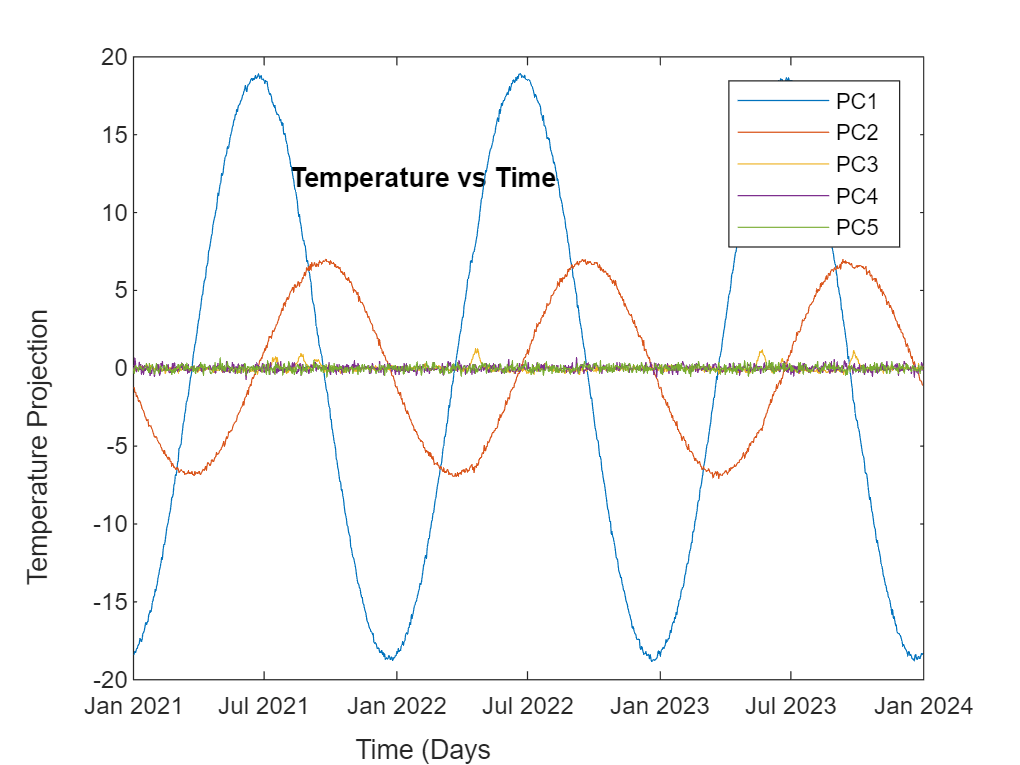

figure 
plot(dates, Aprime(:, 1:5))
title('Temperature vs Time')
xlabel('Time (Days')
ylabel('Temperature Projection')
legend('PC1', 'PC2', 'PC3', 'PC4', 'PC5')

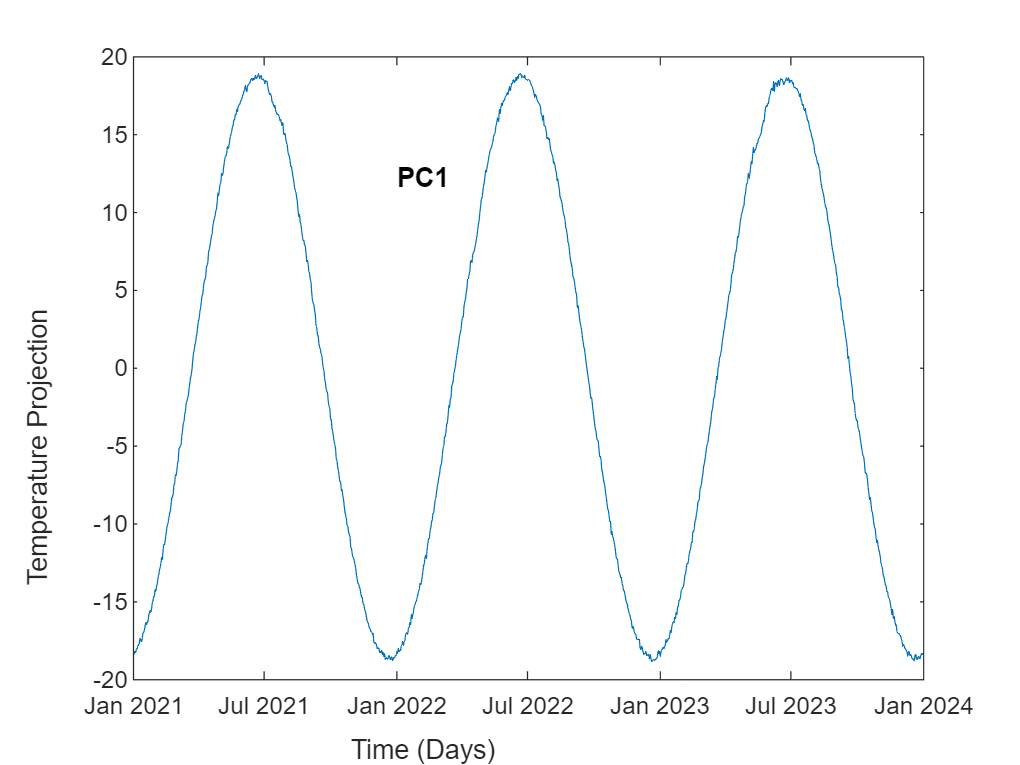

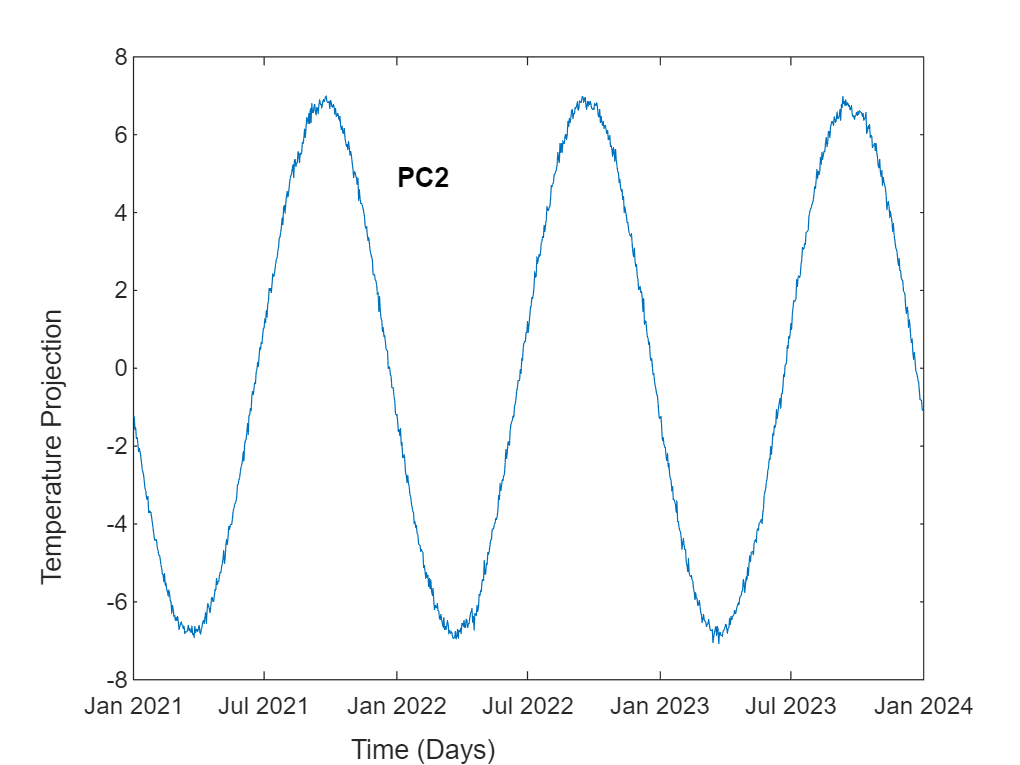

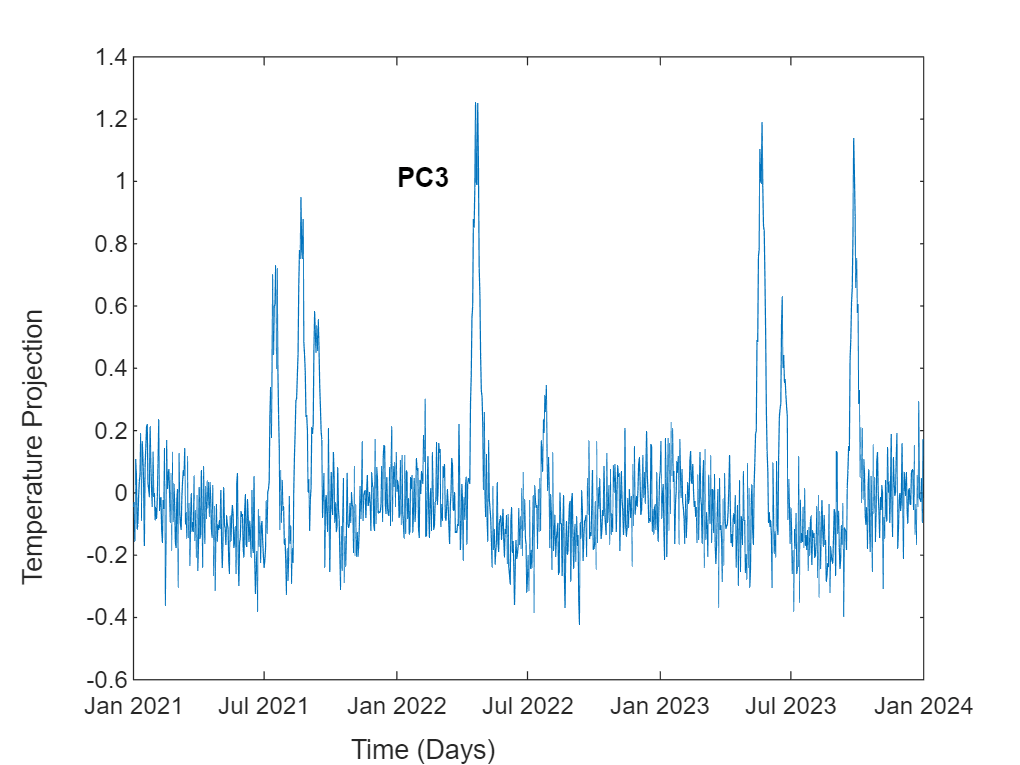

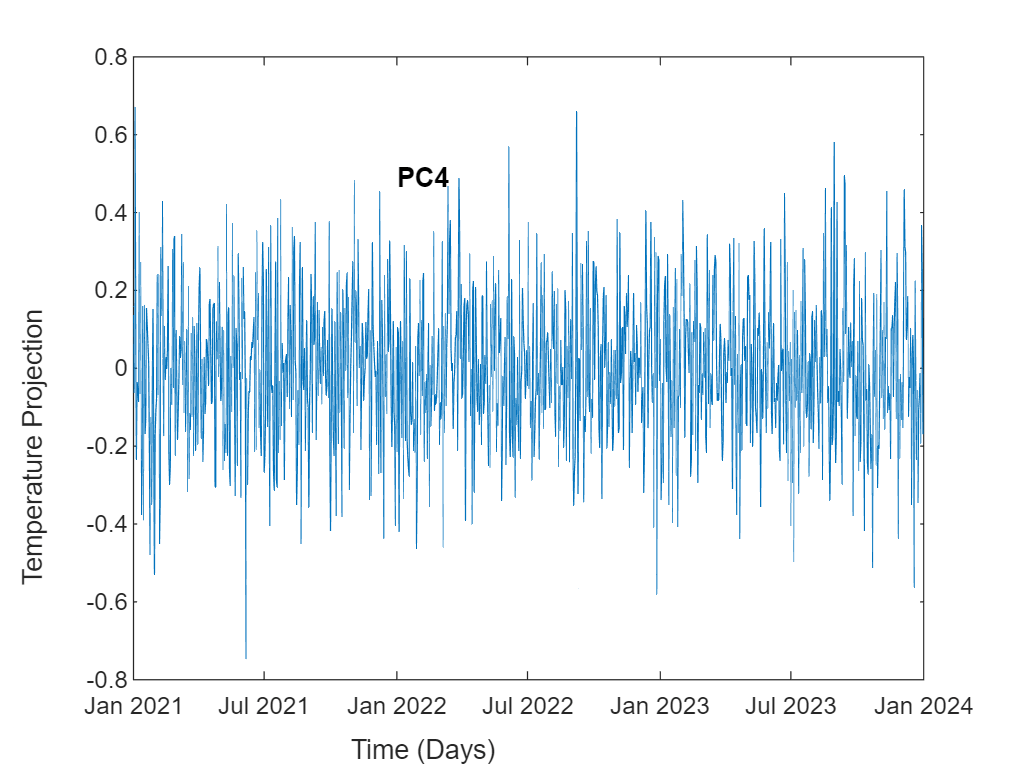

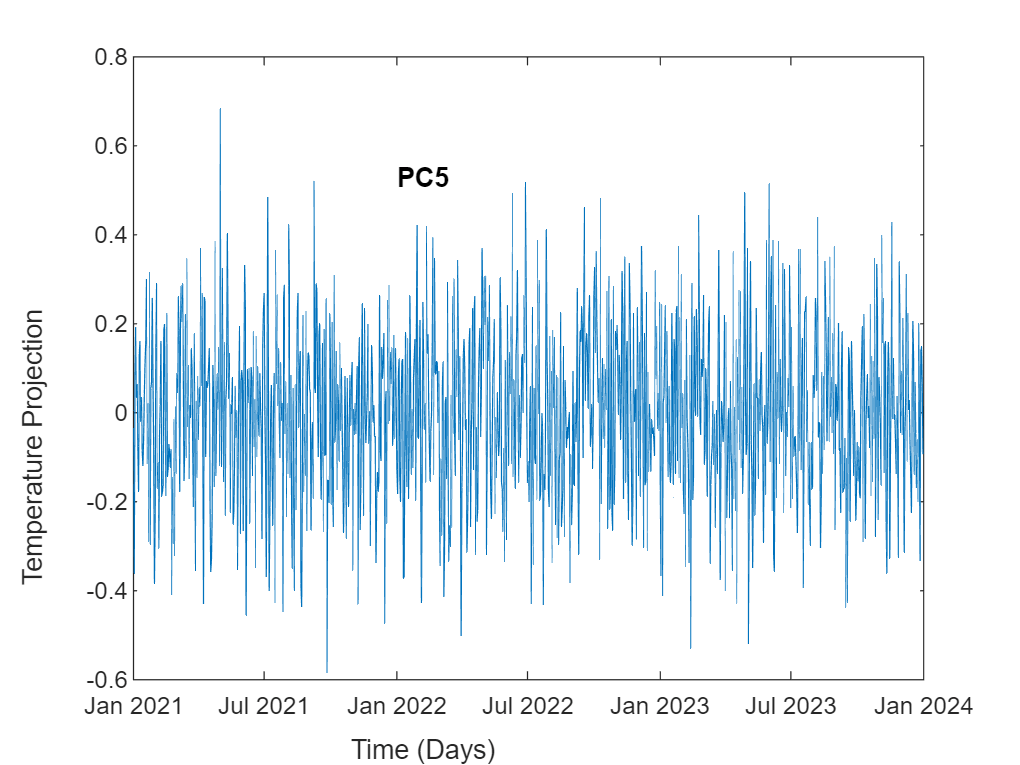


for x = 1:5
    figure 
    plot(dates, Aprime(:, x))
    xlabel('Time (Days)')
    ylabel('Temperature Projection')
    title(['PC', num2str(x)])
    hold off
end

### Step 9: Which weather stations contribute to each principal component?

Visualize the spatial influence of each principal component by plotting the PCA loadings (weights) for each weather station on a geographic map.

**Explanation:**

-  After PCA, the loadings for each principal component represent the influence (or "weight") that each weather station has on that component. Higher loadings mean that the temperature variations at that station significantly contribute to the patterns captured by that component.

-  Plotting these loadings on a map helps identify if certain geographical areas, like coastal or inland regions, are more strongly associated with specific components.

**Instructions:**

- Use the latitude and longitude values in the `stations.csv` data.

- For each component (e.g., PC1, PC2, etc.), create a scatter plot where each weather station's coordinates are marked, and the color of each point represents the magnitude of the loading for that component.

- For example, use a color gradient (e.g., blue to red) to show low to high loadings.

- This visualization will help you interpret the spatial patterns captured by each component

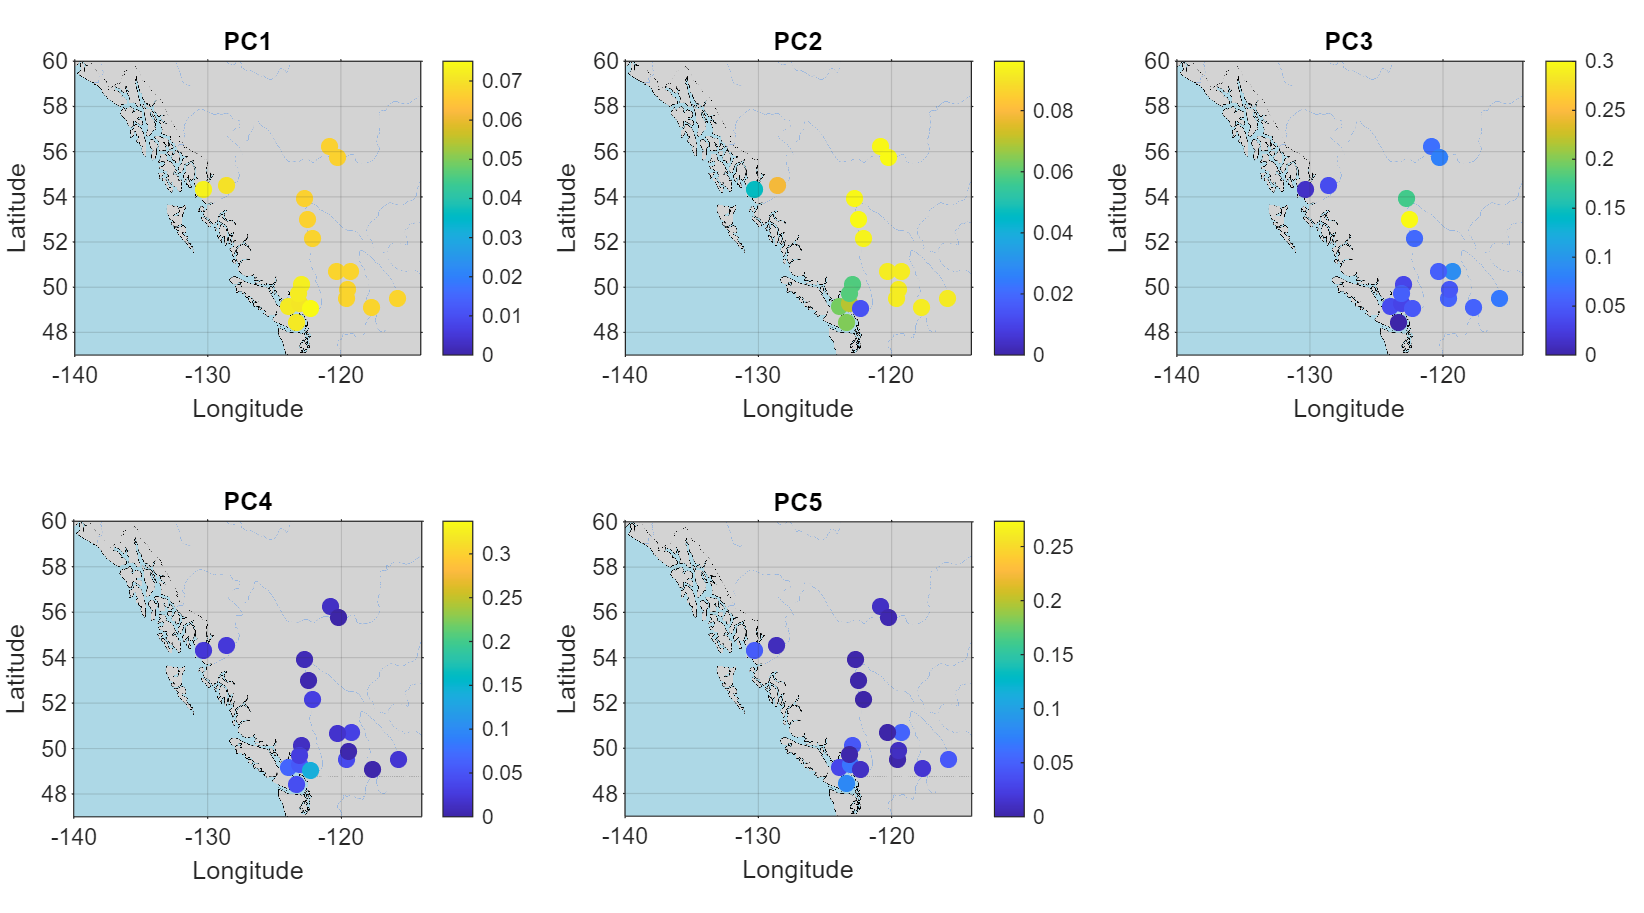

n_comp_to_plot = 5;

hf = figure;
hf.Position(3:4) = [1800, 1000];
tiledlayout(2, 3, 'Padding', 'none', 'TileSpacing', 'compact');

for x = 1:n_comp_to_plot
    nexttile
    showmap 

    hold on 
    scatter(long, lat, 50, abs(Vsorted(:, x)), 'filled');
    title(['PC', num2str(x)])
    xlabel('Longitude')
    ylabel('Latitude')

    ax = gca;
    ax.CLim(1) = 0;
    colorbar
end

### Interpretation

Weather patterns are complex and influenced by several factors, including incident sunlight, prevailing winds, sea surface temperature, and atmosphere particulates (like smoke from wildfires).

- Which principal components are capturing general seasonal variations?

- Which principal components capture the effect of sea surface temperature?    (*Hint:* consider the geographical distribution, and that ocean temperature lags seasonal air temperatures)

- Which principal components capture the effect of forest fires? Can you identify where the forest fires are burning?

- Which principal components capture only noise?

## **Part 2: **Using OLS to estimate the trend of the salmon population and wildfire likelihood based on yearly sea surface temperatures

In a dataset separate from Problem 1, scientists have compiled yearly data on three interconnected environmental variables:

- Estimated Salmon Population

- Yearly Trends in Forest Area Burned by Wildfires

- Mean Ocean Temperature for the Same Year

Your task is to analyze this dataset and explore the relationships between these variables. Using the ordinary least squares (OLS) method, you will model these relationships and interpret the ecological insights your analysis provides.

### **Step 1: Import and understand the dataset**

Use the `readtable` command to download the weather trends dataset from [https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/trends.csv.](https://github.com/dtxe/mat188_datasets/raw/refs/heads/main/bcweather/trends.csv.)

salmon_data = readtable('trends.csv')

salmon_data = 93x4 table
    year     temp     salmon_pop    wildfire_hectares_burned
    ____    ______    __________    ________________________

    1932    9.3203    4.7677e+07             820.97         
    1933    9.3467    3.8791e+07             1304.5         
    1934    9.4281     5.838e+07             1380.8         
    1935    9.4253    3.8638e+07             944.96         
    1936    9.5153    5.9124e+07             1065.9         
    1937    9.4278     5.483e+07             2279.2         
    1938    9.7203     3.914e+07             1185.4         
    1939    9.8795    5.3213e+07             1457.2         
    1940    10.063    2.0012e+07               1510         
    1941    10.215    4.4903e+07             1684.4         
    1942     10.11    2.1223e+07             938.75         
    1943    9.8218    2.5862e+07             

Find the array size of the data (number of rows) using the `size` function

[salmon_data_rows salmon_data_cols] = size(salmon_data)

salmon_data_rows = 93

salmon_data_cols = 4

To get an idea of what the data in the table looks like, you can open the table in the "Workspace" by double clicking the name you gave it. Or you can print out a summary of the table in the "Command Window" by using the function `summary() `with your chosen table name in the parenthesis. 

summary(salmon_data)


salmon_data: 93x4 table

Variables:

    year: double
    temp: double
    salmon_pop: double
    wildfire_hectares_burned: double

Statistics for applicable variables:

                                NumMissing          Min              Median             Max               Mean              Std      

    year                            0                  1932              1978              2024              1978           26.9907  
    temp                            0                9.2133           10.2150           11.9017           10.4219            0.8084  
    salmon_pop                      0           -2.8772e+06        3.2471e+07        5.9124e+07        3.1640e+07        1.3561e+07  
    wildfire_hectares_burned        0              221.0577        2.9620e+03             28400        4.9052e+03        4.6577e+03  



### **Step** 2: Initial visualization

Plot how the salmon population and temperature change throughout the years. Use `yyaxis left `and `yyaxis right `to specify the left (salmon popluation) and right axis (temperature) on the same plot. 

Hints for plotting: 

- Use `xlabel` and `ylabel` to set axis titles for your plot

- You can use `xlim `and `ylim `to change the limits of the x axis and y axis values if required

- Use `legend` to label the graphs corresponding to either Temperature or Salmon Population

- Plotting options such as line color and thickness can be added following the first two entries. Example `plot(x,y,"LineWidth",1.5)` will change the thickness of the lines to the input 1.5.

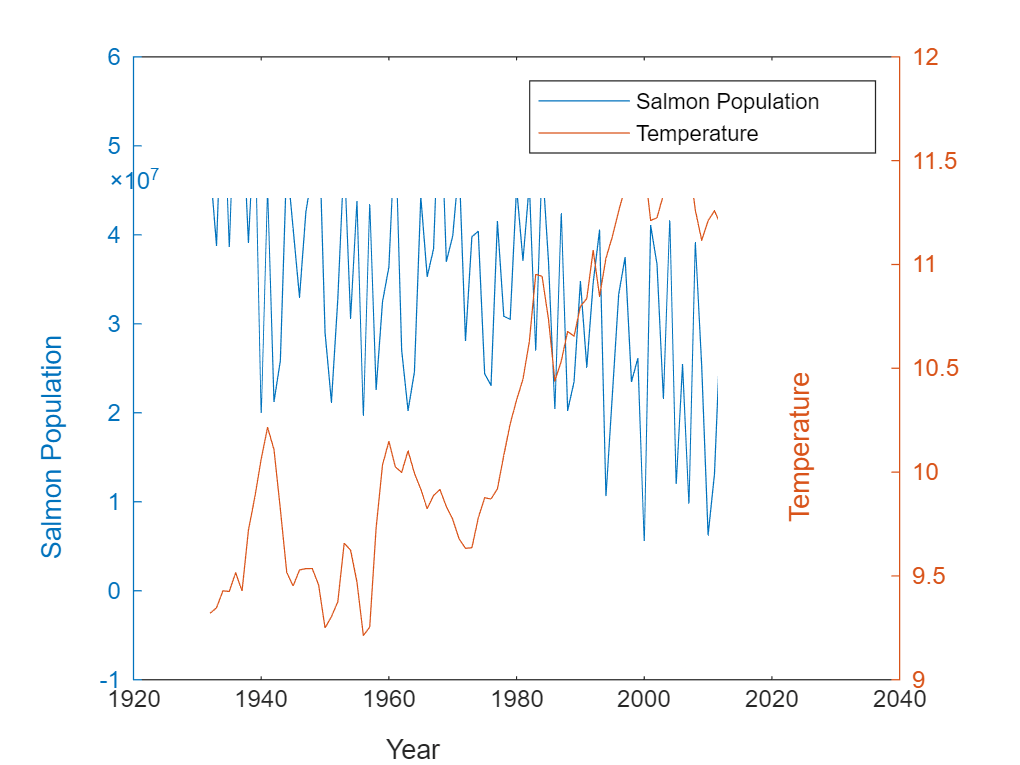

figure 

yyaxis left 
plot(salmon_data.year, salmon_data.salmon_pop)
ylabel('Salmon Population')

yyaxis right 
plot(salmon_data.year, salmon_data.temp)
ylabel('Temperature')
xlabel('Year')

legend('Salmon Population', 'Temperature')

Now, plot how the wildfire changes with temperature throughout the years.

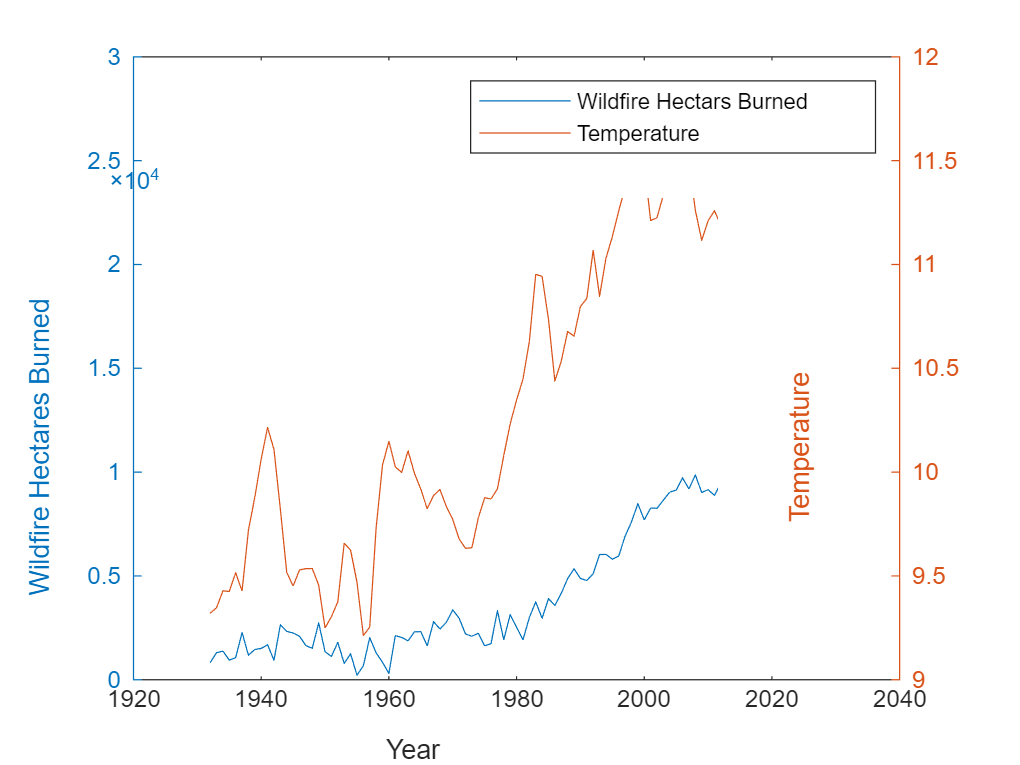

figure 

yyaxis left 
plot(salmon_data.year, salmon_data.wildfire_hectares_burned)
ylabel('Wildfire Hectares Burned')

yyaxis right 
plot(salmon_data.year, salmon_data.temp)
ylabel('Temperature')
xlabel('Year')
legend('Wildfire Hectars Burned', 'Temperature')

### **Step 3: Use projections to perform** **Ordinary Least Squares to estimate the 1st order (linear) and 2nd order (quadratic) models**

Let's start with estimating how the salmon population trend changes with yearly sea temperature. 

Recall the least squares approximation to a solution learned in class that looks like the following:

    
$$\vec{x} ={\left(A^T A\right)}^{-1} A^T \vec{b}$$
  

Consider matrix $\vec{A}$, how can you construct this matrix given the variable temp for both a linear and a quadratic approximation? Hint: concatenate a ones column vector with the appropriate variable(s).  

Hint: you can use function `inv `to take the inverse of a matrix, and a matrix transpose is denoted by the prime `A'. `Remeber, you can use the "Workspace" or "Command Window" to visually see how your matrices look and if their sizes are compatible to perform matrix multiplication. 

% Perform OLS to find 1st order (Linear model)
n_meas = height(salmon_data)

n_meas = 93


Temp1_1st = [ones(n_meas, 1) salmon_data.temp]

Temp1_1st =     1.0000    9.3203
    1.0000    9.3467
    1.0000    9.4281
    1.0000    9.4253
    1.0000    9.5153
    1.0000    9.4278
    1.0000    9.7203
    1.0000    9.8795
    1.0000   10.0632
    1.0000   10.2150


Pop_1st = salmon_data.salmon_pop

Pop_1st = 1.0e+07 *

    4.7677
    3.8791
    5.8380
    3.8638
    5.9124
    5.4830
    3.9140
    5.3213
    2.0012
    4.4903


c_1st = inv(Temp1_1st'*Temp1_1st)*Temp1_1st'*Pop_1st

c_1st = 1.0e+08 *

    1.2913
   -0.0935


% Perform OLS to find 2nd order (Quadratic model)
Temp_2nd = [ones(n_meas, 1) salmon_data.temp salmon_data.temp.^2]

Temp_2nd =     1.0000    9.3203   86.8676
    1.0000    9.3467   87.3602
    1.0000    9.4281   88.8882
    1.0000    9.4253   88.8359
    1.0000    9.5153   90.5405
    1.0000    9.4278   88.8830
    1.0000    9.7203   94.4838
    1.0000    9.8795   97.6054
    1.0000   10.0632  101.2671
    1.0000   10.2150  104.3455


Pop_2nd = salmon_data.salmon_pop

Pop_2nd = 1.0e+07 *

    4.7677
    3.8791
    5.8380
    3.8638
    5.9124
    5.4830
    3.9140
    5.3213
    2.0012
    4.4903


c_2nd = inv(Temp_2nd'*Temp_2nd)*Temp_2nd'*Pop_2nd

c_2nd = 1.0e+08 *

   -1.5208
    0.4455
   -0.0257


Use` linspace` function to create a column vector of 100 linearly spaced temperature values (these will be the x values on your plot)

%xpts = linspace(min(temp),max(temp),100)'; % (100 points is default value)
xfits = linspace(0, max(salmon_data.temp),100)'

xfits =          0
    0.1202
    0.2404
    0.3607
    0.4809
    0.6011
    0.7213
    0.8415
    0.9618
    1.0820


F_1st = [ones(length(xfits), 1), xfits] * c_1st

F_1st = 1.0e+08 *

    1.2913
    1.2800
    1.2688
    1.2575
    1.2463
    1.2350
    1.2238
    1.2126
    1.2013
    1.1901


F_2nd = [ones(length(xfits), 1), xfits, xfits .^ 2] * c_2nd

F_2nd = 1.0e+08 *

   -1.5208
   -1.4676
   -1.4151
   -1.3634
   -1.3125
   -1.2623
   -1.2128
   -1.1641
   -1.1161
   -1.0688


Complete the linear and quadratic model matrices using the temp values from the above step. Recall, we are looking for a linear function $f=c_0 +c_1 x$ and a quadratic function $f=c_0 +c_1 x+c_2 x^2$ that can model the salmon popuation trend with sea temperature. 

% Linear model y values (y = mx+b)
fit_linear = fit(xfits, F_1st, 'poly1')

fit_linear =      Linear model Poly1:
     fit_linear(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -9.354e+06  (-9.354e+06, -9.354e+06)
       p2 =   1.291e+08  (1.291e+08, 1.291e+08)

% Quadratic model y values (y = ax^2 + bx + c)
fit_quadratic = fit(xfits, F_2nd, 'poly2')

fit_quadratic =      Linear model Poly2:
     fit_quadratic(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -2.568e+06  (-2.568e+06, -2.568e+06)
       p2 =   4.455e+07  (4.455e+07, 4.455e+07)
       p3 =  -1.521e+08  (-1.521e+08, -1.521e+08)

### **Step** 4: Plot the raw data, and your fitted curves

Graph the salmon population (as the dependent variable) vs the temperature (as the independent variable) as a scatter plot using the `scatter `command. On the same plot, graph the linear and quaratic models. 

Hints for plotting: To ensure all three graphs are on one plot, make sure to use the `hold on/hold off` commands.

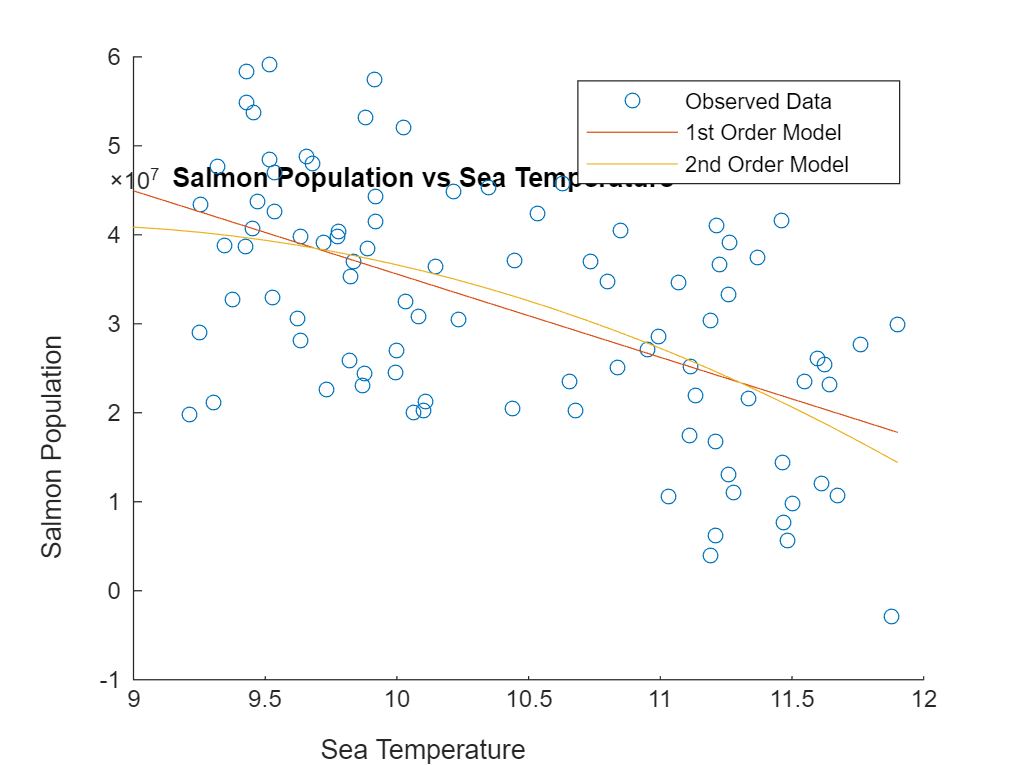

% Plot Salmon popluation vs temperature data, linear and quatratic model 
figure 
scatter(salmon_data.temp, salmon_data.salmon_pop)
hold on 
plot(xfits, F_1st)
plot(xfits, F_2nd)
xlabel('Sea Temperature')
ylabel('Salmon Population')
title('Salmon Population vs Sea Temperature')
legend('Observed Data', '1st Order Model', '2nd Order Model')
xlim([9 12])
ylim([-1*10^7 6*10^7])

**By visual inspection, which model provides the best fit for the data? **In other words, what's the minimum order of the model (1st, or 2nd order) that adequately captures most of the dependent variation in the data based on the plot? Why do you think so?

### **Step 5: Analyze trends for wildfires**

**Repeat the above steps except now replace the salmon population data with the wildfire data. **

% Perform OLS to find 1st order (Linear model)
n_meas = height(salmon_data)

n_meas = 93

Temp1_1st = [ones(n_meas, 1) salmon_data.temp]

Temp1_1st =     1.0000    9.3203
    1.0000    9.3467
    1.0000    9.4281
    1.0000    9.4253
    1.0000    9.5153
    1.0000    9.4278
    1.0000    9.7203
    1.0000    9.8795
    1.0000   10.0632
    1.0000   10.2150


Fire_1st = salmon_data.wildfire_hectares_burned

Fire_1st = 1.0e+04 *

    0.0821
    0.1305
    0.1381
    0.0945
    0.1066
    0.2279
    0.1185
    0.1457
    0.1510
    0.1684


c1_1st = inv(Temp1_1st'*Temp1_1st)*Temp1_1st'*Fire_1st

c1_1st = 1.0e+04 *

   -4.1407
    0.4444


% Perform OLS to find 2nd order (Quadratic model)
Temp1_2nd = [ones(n_meas, 1) salmon_data.temp salmon_data.temp.^2]

Temp1_2nd =     1.0000    9.3203   86.8676
    1.0000    9.3467   87.3602
    1.0000    9.4281   88.8882
    1.0000    9.4253   88.8359
    1.0000    9.5153   90.5405
    1.0000    9.4278   88.8830
    1.0000    9.7203   94.4838
    1.0000    9.8795   97.6054
    1.0000   10.0632  101.2671
    1.0000   10.2150  104.3455


Fire_2nd = salmon_data.wildfire_hectares_burned

Fire_2nd = 1.0e+04 *

    0.0821
    0.1305
    0.1381
    0.0945
    0.1066
    0.2279
    0.1185
    0.1457
    0.1510
    0.1684


c1_2nd = inv(Temp1_2nd'*Temp1_2nd)*Temp1_2nd'*Fire_2nd

c1_2nd = 1.0e+05 *

    1.5437
   -0.3308
    0.0179


% Create a column of 100 linearly spaced x values for plotting (ensure it
% encompases all of data)
x1fits = linspace(0, max(salmon_data.temp),100)'

x1fits =          0
    0.1202
    0.2404
    0.3607
    0.4809
    0.6011
    0.7213
    0.8415
    0.9618
    1.0820


F1_1st = [ones(length(x1fits), 1), x1fits] * c1_1st

F1_1st = 1.0e+04 *

   -4.1407
   -4.0873
   -4.0339
   -3.9805
   -3.9270
   -3.8736
   -3.8202
   -3.7668
   -3.7134
   -3.6599


F1_2nd = [ones(length(xfits), 1), x1fits, x1fits .^ 2] * c1_2nd

F1_2nd = 1.0e+05 *

    1.5437
    1.5042
    1.4652
    1.4267
    1.3888
    1.3513
    1.3144
    1.2780
    1.2421
    1.2067


% Linear model y values (y = mx+b)
fit_linear = fit(x1fits, F_1st, 'poly1')

fit_linear =      Linear model Poly1:
     fit_linear(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -9.354e+06  (-9.354e+06, -9.354e+06)
       p2 =   1.291e+08  (1.291e+08, 1.291e+08)

% Quadratic model y values (y = ax^2 + bx + c)
fit_quadratic = fit(xfits, F_2nd, 'poly2')

fit_quadratic =      Linear model Poly2:
     fit_quadratic(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =  -2.568e+06  (-2.568e+06, -2.568e+06)
       p2 =   4.455e+07  (4.455e+07, 4.455e+07)
       p3 =  -1.521e+08  (-1.521e+08, -1.521e+08)

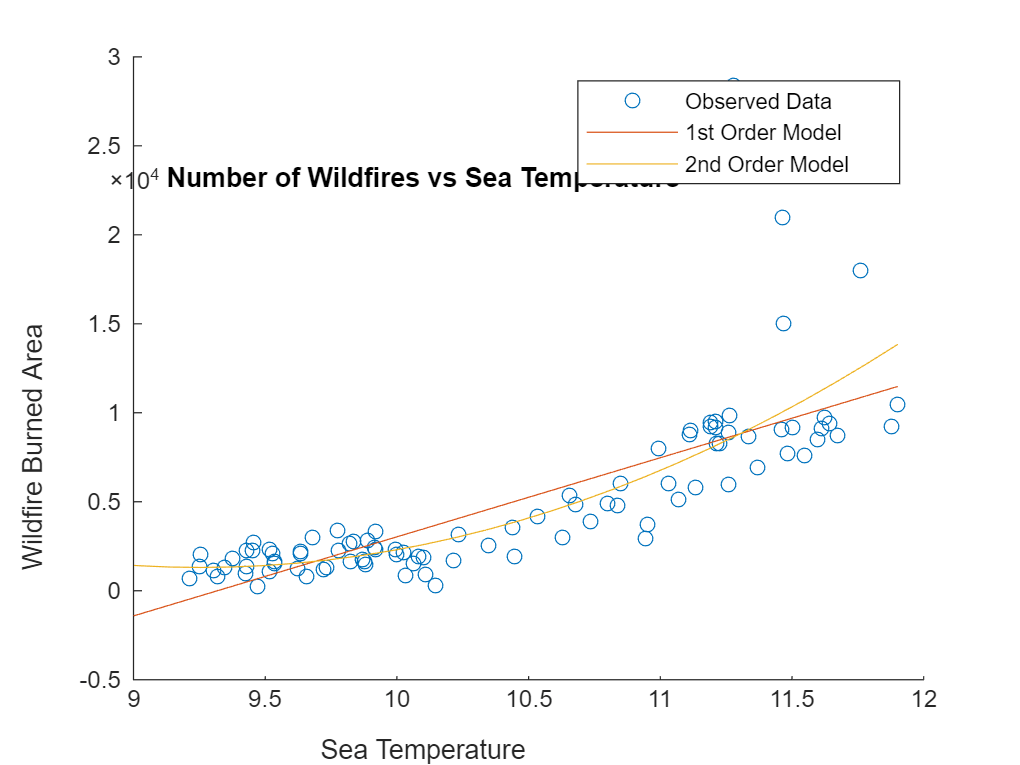

% Plot Wildfire popluation vs temperature data, linear and quadratic model
figure 
scatter(salmon_data.temp, salmon_data.wildfire_hectares_burned)
hold on 
plot(x1fits, F1_1st)
plot(x1fits, F1_2nd)
xlabel('Sea Temperature')
ylabel('Wildfire Burned Area')
title("Number of Wildfires vs Sea Temperature")
legend('Observed Data', '1st Order Model', '2nd Order Model')
xlim([9 12])
ylim([-0.5*10^4 3*10^4])

**By visual inspection, which model provides the best fit for the data? **In other words, what's the minimum order of the model (1st, or 2nd order) that adequately captures most of the dependent variation in the data based on the plot? Why do you think so?

**Well done! You've successfully completed Homework 5!** 🎉🥳

We hope this provided a demonstration of the power of linear algebra and computation software in working with and manipulating, isolating trends in, and extracting insights from large datasets.

### Submission instructions

- Run this Live Script from top to bottom to verify the correctness of your code. (Home tab > Clear Workspace; Live Editor tab > Run)

- Export this Live Script as a PDF file (Live Editor > Export)

- Upload **both the MLX and PDF **files to Gradescope

### Helper functions

**⚠️ Do not delete the code below. ⚠**️

These functions exist to reduce the complexity of the assignment above, by abstracting away concepts that aren't core to the course curriculum. However, feel free to take a look if you're curious!

function [] = showmap()
map = imread('https://raw.githubusercontent.com/dtxe/mat188_datasets/refs/heads/main/bcweather/map_tight.png');   % download map background
imshow(flipud(map), 'XData', [-140, -114], 'YData', [47, 60]);                                                    % display as image

% configure plot
ax = gca();
ax.YDir = 'normal';
daspect([1.7 1 1]);
axis on
grid on
end

function tf = iszero(A)
tf = all(A(:) < 1e-10);
end